# Denoising Work Flow

## Add Files

addpath 'GT Folder'
addpath 'Real Noisy Images Folder'
addpath 'Common Functions'

## Load Image

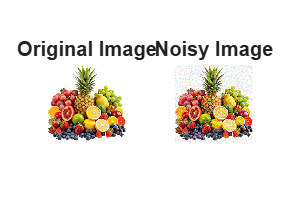

Image_name = 'fruits_imageGT.png';
%Image_name = 'balloons_noisy.png';

GT_substring = contains(Image_name, 'GT');
% Initialisation
d = 8; % depth of the n/w
imsize = -1;

if GT_substring
    % Get the ground truth image
    I = imread(fullfile('GT Folder', Image_name));
    img = imresize(I, [256 256]);
    %img = get_image(image, imsize);
    %img = crop_image(img, d);
    % Add noise to the image
    noisyImg = imnoise(img, 'gaussian', 0, 0.01); % Add Gaussian noise to the image
    % Display the original and noisy images for comparison
    figure;
    subplot(1, 2, 1), imshow(img), title('Original Image');
    subplot(1, 2, 2), imshow(noisyImg), title('Noisy Image');

elseif ~GT_substring
    % Load noisy image
    I = imread(fullfile('Real Noisy Images Folder', Image_name));
    noisyImg = imresize(I, [256 256]);
    %noisyImg = get_image(image, imsize);
    %noisyImg = crop_image(noisyImg, d);
    % Display the loaded noisy image
    figure;
    imshow(noisyImg), title('Loaded Noisy Image');
else
    assert(false, 'File Path or File name invalid')
end

## Define CNN and Noise Tensor

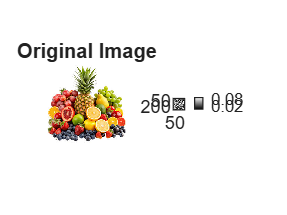

% --- Create Noise Tensor ---
input_depth = 3;
method = 'noise';
spatial_size = size(noisyImg, 1);
net_input = get_noise(input_depth, method, spatial_size);

%Visualize Noise
imagesc(net_input(:,:,2))
axis image
colormap gray
colorbar


% --- Create CNN ---
num_layers = d;
num_channels = 64;
num_classes = 3;
kernel_size = 3;
[a, b, ~] = size(noisyImg);
imgSize = [a, b, input_depth]; % Set the image size for the CNN

%net = buildCNN(num_layers, num_channels, kernel_size, imgSize, input_depth);
%net = DipUnet3(imgSize, num_classes);
net = InpaintUnet3(imgSize, num_classes);

% Compute number of parameters
totalParams = 0;
lrnables = net.Learnables;
for i = 1:height(lrnables)
    param = lrnables.Value{i};
    totalParams = totalParams + numel(extractdata(param));
end
fprintf('Number of params: %d\n', totalParams);

Number of params: 1023203



% --- Define The Loss Function ---
%loss = mean((out - img_noisy).^2,'all');


function loss = computeLoss(out, img_noisy, lambda_tv) 
 
mse_loss = mean((out - img_noisy).^2, 'all'); 
%Total Variation: penalise spatial gradients in output 
dx = out(:, 2:end, :, :) - out(:,1:end-1, :, :); 
dy = out(2:end, :, :, :) - out(1:end-1, :, :, :); 
tv_loss = mean(abs(dx),'all') + mean(abs(dy), 'all'); 
loss = mse_loss + lambda_tv * tv_loss; 
end 
% Suggested: lambda_tv = 1e-4 to 1e-3 (tune for noise level)

## Optimization Step 1

function [loss, gradients, out, out_avg] = modelGradients(net, net_input_saved, img_noisy, out_avg, exp_weight, reg_noise_std)

    img_noisy = dlarray(img_noisy,'SSCB');

    if reg_noise_std > 0
        noise = randn(size(extractdata(net_input_saved)), 'single');
        noise = dlarray(noise, 'SSCB');
        net_input = net_input_saved + noise*reg_noise_std;
    else
        net_input = net_input_saved;
    end

    % Forward pass
    out = forward(net, net_input);

    % Loss (MSE)
    loss = mean((out - img_noisy).^2,'all');
    %loss = computeLoss(out, img_noisy, 1e-32);

    % Output smoothing (detach)
    out_detached = dlarray(extractdata(out),'SSCB');

    if isempty(out_avg)
        out_avg = out_detached;
    else
        out_avg = out_avg*exp_weight + out_detached*(1-exp_weight);
    end

    % Gradients
    gradients = dlgradient(loss, net.Learnables);

end

## Optimization Step 2

Iteration 00001 Loss 0.184569 PSNR_noisy: 7.3384 PSNR_gt: 7.1097 PSNR_gt_sm: 7.1097
Iteration 00002 Loss 0.166012 PSNR_noisy: 7.7986 PSNR_gt: 7.5740 PSNR_gt_sm: 7.1273
Iteration 00003 Loss 0.172674 PSNR_noisy: 7.6277 PSNR_gt: 7.4001 PSNR_gt_sm: 7.1433
Iteration 00004 Loss 0.158361 PSNR_noisy: 8.0035 PSNR_gt: 7.7806 PSNR_gt_sm: 7.1622
Iteration 00005 Loss 0.149458 PSNR_noisy: 8.2548 PSNR_gt: 8.0312 PSNR_gt_sm: 7.1844
Iteration 00006 Loss 0.146731 PSNR_noisy: 8.3348 PSNR_gt: 8.1203 PSNR_gt_sm: 7.2054
Iteration 00007 Loss 0.145352 PSNR_noisy: 8.3758 PSNR_gt: 8.1454 PSNR_gt_sm: 7.2264
Iteration 00008 Loss 0.144110 PSNR_noisy: 8.4131 PSNR_gt: 8.1912 PSNR_gt_sm: 7.2475
Iteration 00009 Loss 0.143838 PSNR_noisy: 8.4213 PSNR_gt: 8.2064 PSNR_gt_sm: 7.2690
Iteration 00010 Loss 0.134382 PSNR_noisy: 8.7166 PSNR_gt: 8.5101 PSNR_gt_sm: 7.2930
Iteration 00011 Loss 0.137102 PSNR_noisy: 8.6296 PSNR_gt: 8.4115 PSNR_gt_sm: 7.3151
Iteration 00012 Loss 0.131447 PSNR_noisy: 8.8125 PSNR_gt: 8.5995 PSNR_gt_sm:

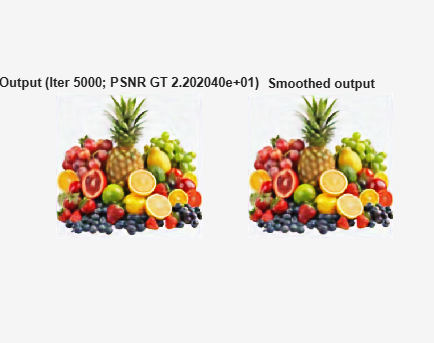

trailingAvg   = [];
trailingAvgSq = [];
reg_noise_std = 1/30;

if GT_substring
    img_gt = img;
    img_gt = im2double(img_gt);
end

PLOT = 1; % 1 for plotting and 0 otherwise
LR = 1e-4;
show_every = 10;
exp_weight = 0.99;
num_iter = 10000;
out_avg = [];
last_net = [];
last_learnables = [];
psrn_noisy_last = 0;
psnr_noisy_last = -inf;


noisyImg_nom = im2double(noisyImg);

% Convert net_input to dlarray format
%net_input = dlarray(net_input, 'SSCB');
%net_input_saved = dlarray(net_input, 'SSCB');
net_input_saved = dlarray(single(net_input), 'SSCB');

% --- Training Loop ---
for iter = 1:num_iter
    % Call function for forward pass
    [loss, gradients, out, out_avg] = dlfeval(@modelGradients, net, net_input_saved, noisyImg_nom, out_avg, exp_weight, reg_noise_std);
    
    
    [net, trailingAvg, trailingAvgSq] = adamupdate(net, gradients,trailingAvg, trailingAvgSq, iter, LR);
    

    % --- Convert dlarray to numeric ---
    out_num = double(gather(extractdata(out)));
    out_num = out_num(:,:,:,1);
    out_avg_num = double(gather(extractdata(out_avg)));
    out_avg_num = out_avg_num(:,:,:,1);

    noisyImg_num = im2double(noisyImg);

    %--- Compute PSNR ---
    psnr_noisy = psnr(out_num, noisyImg_num);
    if GT_substring
        img_numGT = im2double(img_gt);
        psnr_gt = psnr(out_num, img_numGT);
        psnr_gt_sm = psnr(out_avg_num, img_numGT);
        % --- Print Loss and PSNR ---
        fprintf('Iteration %05d Loss %.6f PSNR_noisy: %.4f PSNR_gt: %.4f PSNR_gt_sm: %.4f\r', iter,gather(extractdata(loss)),...
        psnr_noisy, psnr_gt, psnr_gt_sm);
    else
        % --- Print Loss and PSNR ---
        fprintf('Iteration %05d Loss %.6f PSNR_noisy: %.4f\r', iter,gather(extractdata(loss)),...
        psnr_noisy);
    end
    
    % --- Start Plotting ---
    if PLOT && mod(iter, show_every) == 0
        % Clip to [0, 1]
        out_plt = min(max(out_num, 0), 1);
        out_avg_plt = min(max(out_avg_num, 0), 1);
        % Plot side by side
        fig = figure(1); clf
        set(fig, 'Visible', 'on');
        subplot(1,2,1);
        imagesc(out_plt); colormap gray; axis image off;
        if GT_substring
            title(sprintf('Output (Iter %d; PSNR GT %d)', iter,psnr_gt));
        else
            title(sprintf('Output (Iter %d; PSNR Noisy %d)', iter,psnr_noisy));
        end

        subplot(1,2,2);
        imagesc(out_avg_plt); colormap gray; axis image off;
        title('Smoothed output')
        drawnow 
    end

    % --- Back Tracking Logic ---
    if  mod(iter, show_every) ~= 0
        if psnr_noisy - psnr_noisy_last < -5
            fprintf('\n Falling back to previous checkpoint.\n');
            % Restore weights
            net.Learnables.Value = last_learnables;
            break; % stop training
        else
            % Save current weights
            last_learnables = net.Learnables.Value;
            psnr_noisy_last = psnr_noisy;
        end
    end

end

## See